clear all;

main_dir='E:\Github\MATLAB-atomic-calculation\MOT\';

## Loading slower on

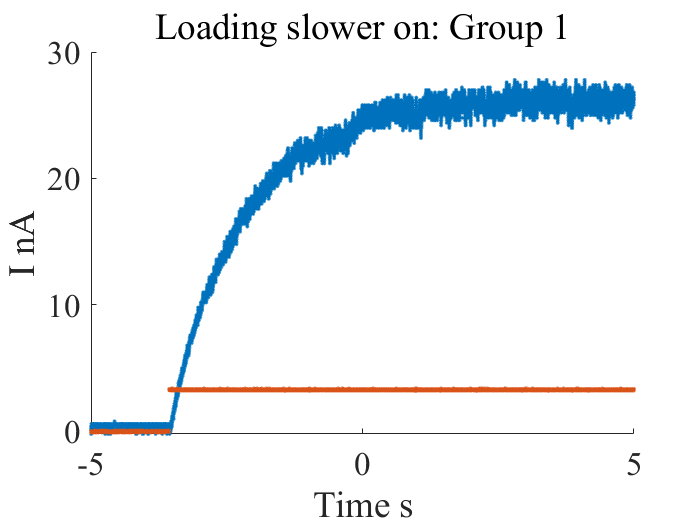

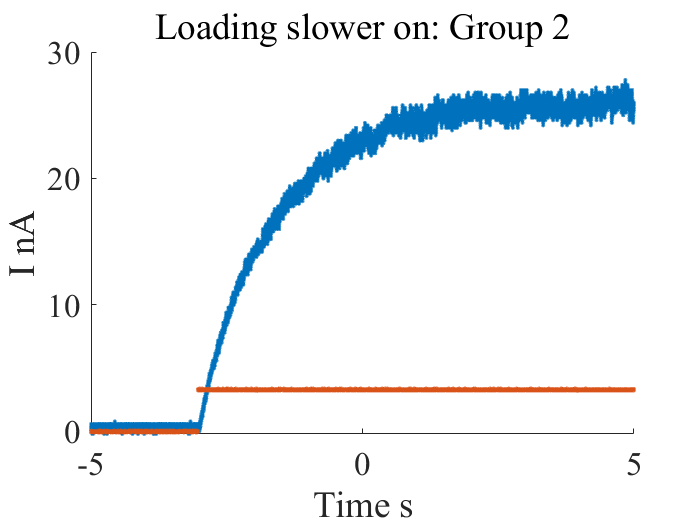

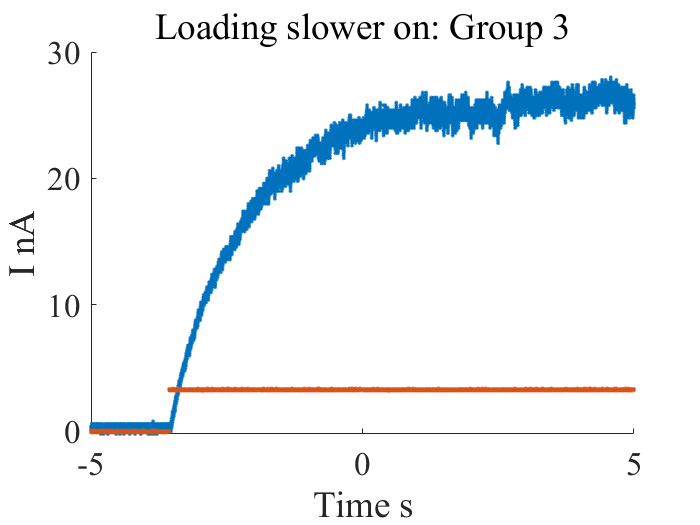

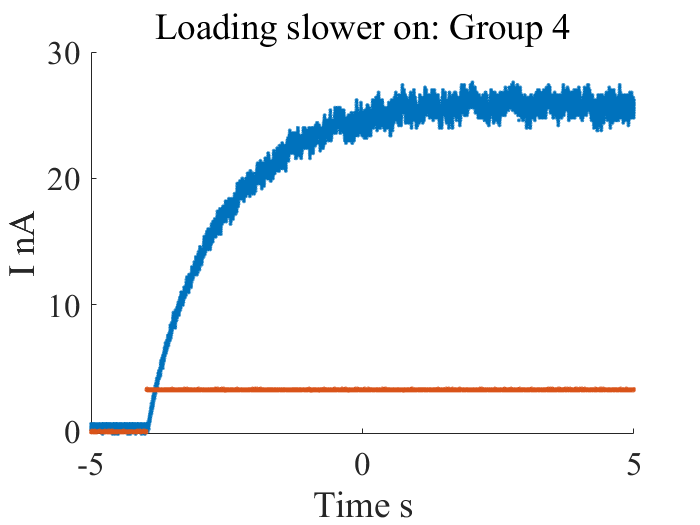

% Seperate plot
for i=1:4
    filename=[main_dir,'slower_on_',num2str(i),'(5nA)'];
    load(filename);
    signal=signal*5;
    f=figure;
    scatter(time,signal,'.');
    hold on;
    scatter(time,trigger,'.');
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title(['Loading slower on: Group ',num2str(i)]);
end

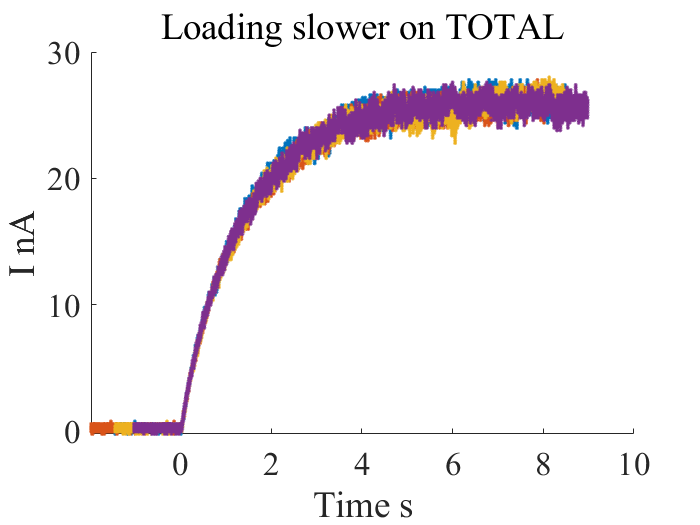


%Total plot
f=figure;

for i=1:4
    filename=[main_dir,'slower_on_',num2str(i),'(5nA)'];
    load(filename);
    signal=signal*5;
    [starttime(i),start_seq(i)]=ref_time(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    scatter(calibrate_time(:,i),signal,'.');
    hold on;
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Loading slower on TOTAL');
end

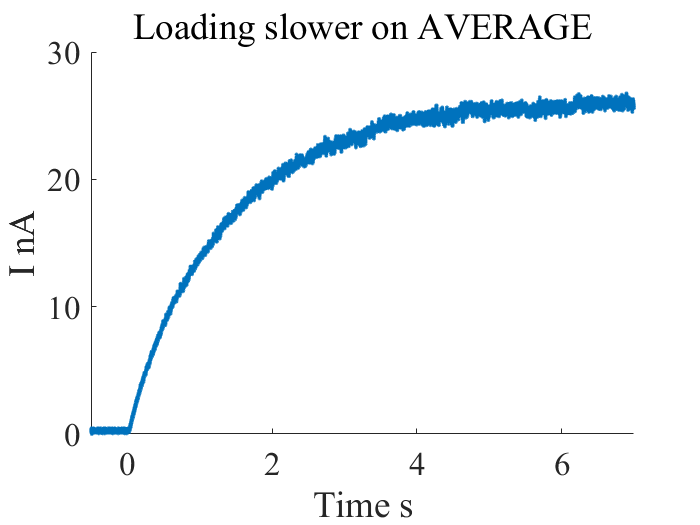



for i=1:4
    filename=[main_dir,'slower_on_',num2str(i),'(5nA)'];
    load(filename);
    signal=signal*5;
    [starttime(i),start_seq(i)]=ref_time(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    [i_start,i_end]=datacut(calibrate_time(:,i),-0.5,7);

    i_end=i_start+75000;

    for j=i_start:i_end
        final_time_on(j-i_start+1)=calibrate_time(j,i);
    end
    for j=i_start:i_end
        final_signal(j-i_start+1,i)=signal(j);
    end
end
final_signal_on_average=mean(final_signal,2);

    figure;
    scatter(final_time_on,final_signal_on_average,'.');
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Loading slower on AVERAGE');
    xlim([-0.5,7]);

    savefig([main_dir,'Loading slower on.fig']);

## Loading slower off

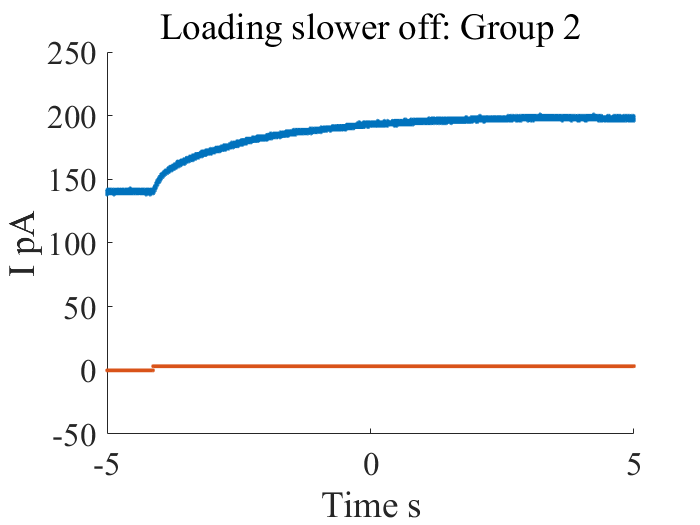

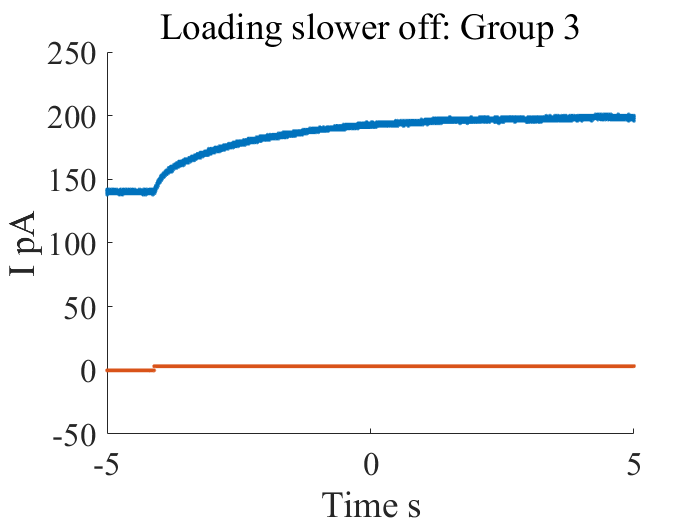

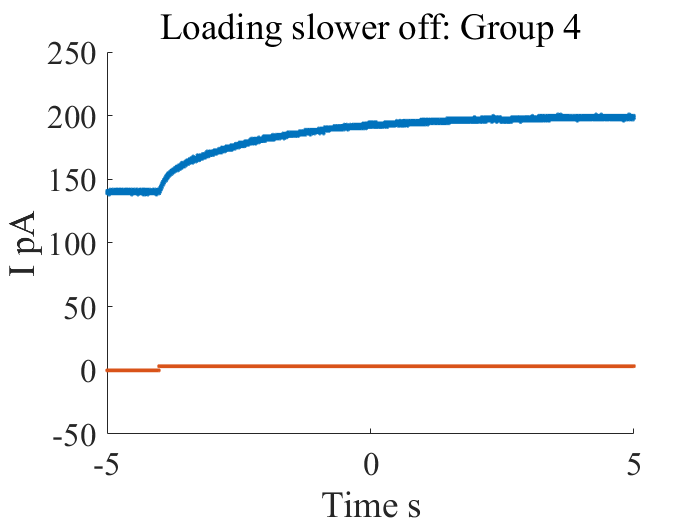

clear final_signal;
% Seperate plot
for i=2:4
    filename=[main_dir,'slower_off_',num2str(i),'(50pA)'];
    load(filename);
    signal=signal*50;
    f=figure;
    scatter(time,signal,'.');
    hold on;
    scatter(time,trigger,'.');
    ylabel('I pA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title(['Loading slower off: Group ',num2str(i)]);
end

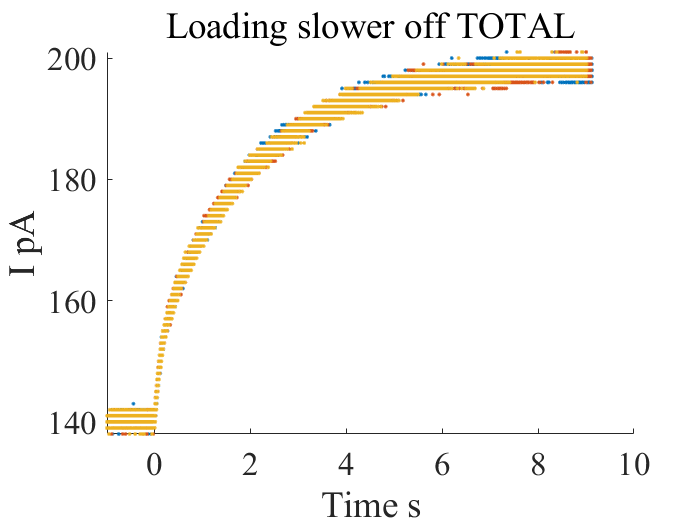


%Total plot
f=figure;

for i=2:4
    filename=[main_dir,'slower_off_',num2str(i),'(50pA)'];
    load(filename);
    signal=signal*50;
    [starttime(i),start_seq(i)]=ref_time(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    scatter(calibrate_time(:,i),signal,'.');
    hold on;
    ylabel('I pA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Loading slower off TOTAL');
end

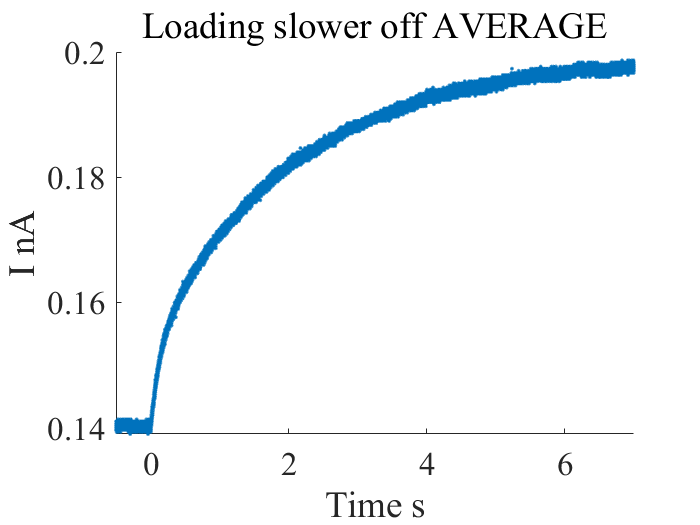



for i=2:4
    filename=[main_dir,'slower_off_',num2str(i),'(50pA)'];
    load(filename);
    signal=signal*50;
    [starttime(i),start_seq(i)]=ref_time(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    [i_start,i_end]=datacut(calibrate_time(:,i),-0.5,7);

    i_end=i_start+75000;

    for j=i_start:i_end
        final_time_off(j-i_start+1)=calibrate_time(j,i);
    end
    for j=i_start:i_end
        final_signal(j-i_start+1,i)=signal(j);
    end
end
final_signal(:,1)=[];
final_signal_off_average=mean(final_signal,2);

    figure;
    scatter(final_time_off,final_signal_off_average/1000,'.');
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Loading slower off AVERAGE');
    xlim([-0.5,7]);

    savefig([main_dir,'Loading slower off.fig']);

## Slower hybrid plot

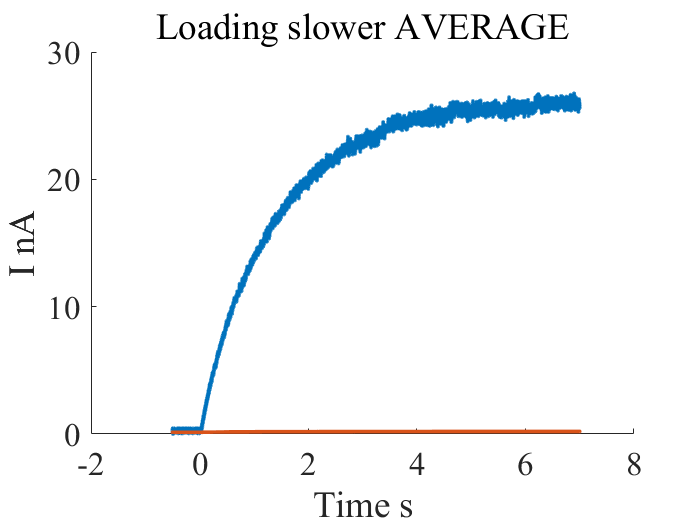

figure;
scatter(final_time_on,final_signal_on_average,'.');
hold on;
scatter(final_time_off,final_signal_off_average/1000,'.'); %nA
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Loading slower AVERAGE');

## Decay

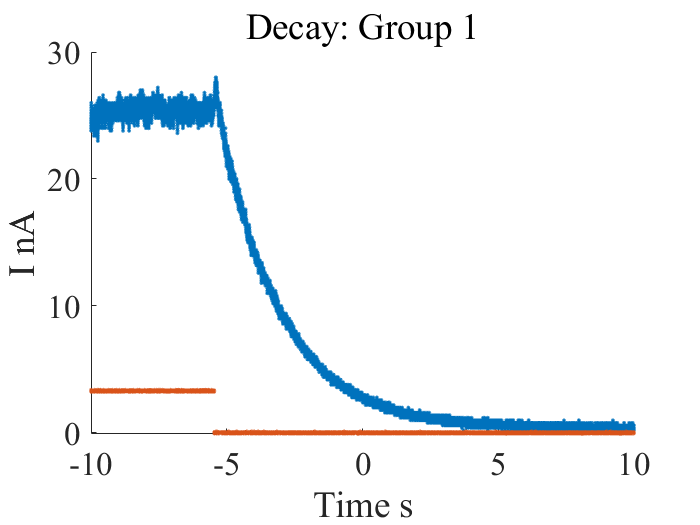

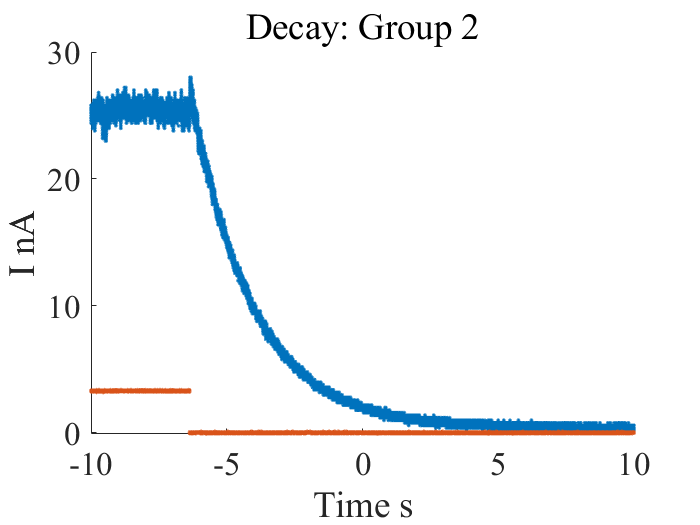

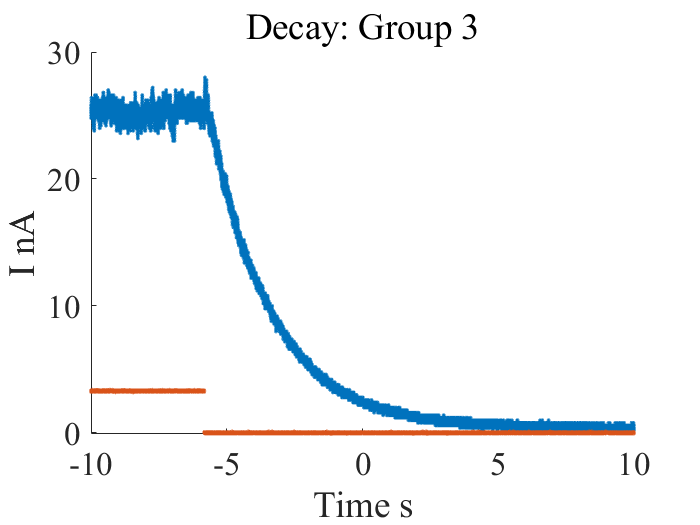

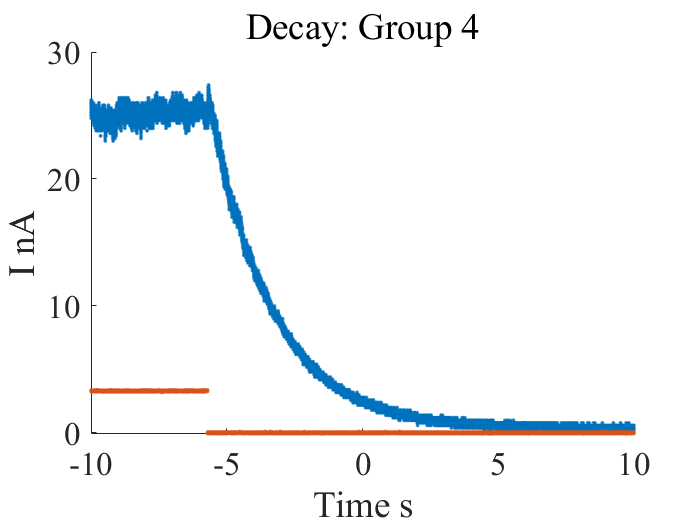

clear final_signal;
% Seperate plot
for i=1:4
    filename=[main_dir,'decay_',num2str(i)];
    load(filename);
    signal=signal*5;
    f=figure;
    scatter(time,signal,'.');
    hold on;
    scatter(time,trigger,'.');
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title(['Decay: Group ',num2str(i)]);
end

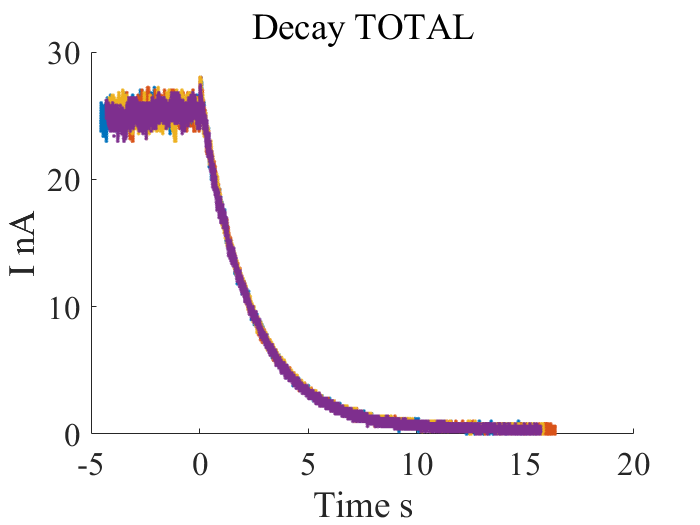


%Total plot
f=figure;

for i=1:4
    filename=[main_dir,'decay_',num2str(i)];
    load(filename);
    signal=signal*5;
    [starttime(i),start_seq(i)]=ref_time_decay(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    scatter(calibrate_time(:,i),signal,'.');
    hold on;
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Decay TOTAL');
end

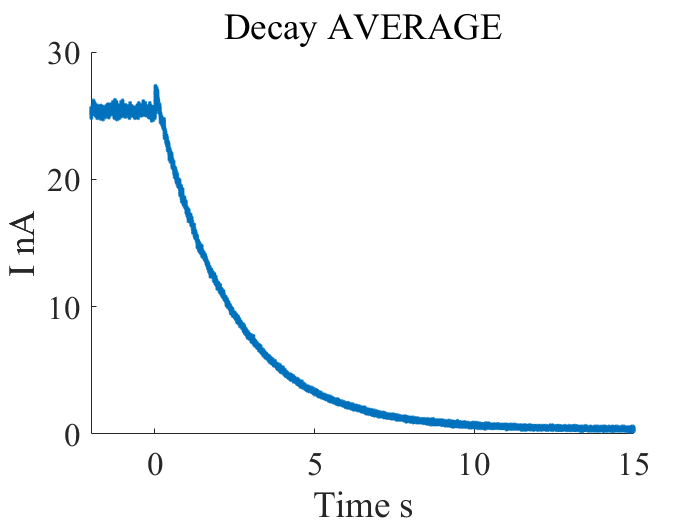



for i=1:4
    filename=[main_dir,'decay_',num2str(i)];
    load(filename);
    signal=signal*5;
    [starttime(i),start_seq(i)]=ref_time_decay(time,trigger);
    calibrate_time(:,i)=time-starttime(i);
    [i_start,i_end]=datacut(calibrate_time(:,i),-2,15);

    i_end=i_start+85000;

    for j=i_start:i_end
        final_time_decay(j-i_start+1)=calibrate_time(j,i);
    end
    for j=i_start:i_end
        final_signal(j-i_start+1,i)=signal(j);
    end
end

final_signal_decay_average=mean(final_signal,2);

    figure;
    scatter(final_time_decay,final_signal_decay_average,'.');
    ylabel('I nA');
    xlabel('Time s');
    set(gca,'fontname','times new roman','fontsize',20);
    title('Decay AVERAGE');
    xlim([-2,15]);

    savefig([main_dir,'Decay.fig']);

function [result,i]=ref_time(time,trigger)
    for i=1:length(time)
        if trigger(i)>2
            break
        end
        result=time(i);
    end
end

function [result,i]=ref_time_decay(time,trigger)
    for i=1:length(time)
        if trigger(i)<2
            break
        end
        result=time(i);
    end
end

function [i_start,i_end]=datacut(original_time,time_start,time_end)
    for i=1:length(original_time)
        if original_time(i)>time_start
            i_start=i;
            break;
        end
    end
    for i=1:length(original_time)
        if original_time(i)>time_end
            i_end=i;
            break;
        end
    end
end